       Aryan Ranjan

20112026

## **Indian Institute of Technology Roorkee**

### **Autumn Semester: 2022-23**

#### **Tutorial 1**

% Clearing memory and terminal 
% and measuring runtime
clear;
clc;
tic;

Q1. Convert the following system of equations into matrix format...

% Sol 1

A = [3, 2, 4; 1, -2, 0; -1, 3, 2];
B = [14; -7; -2];

A

A =      3     2     4
     1    -2     0
    -1     3     2


B

B =     14
    -7
    -2


Q2. Two matrices A and B are defined as follows.....

% Sol 2

%{ 
a) Yes, As No. of Cols in A  = No. of Rows in B. 
   Now, calculating A*B and B*A
%}

A = [3, 7, 1; -2, 1, -3];
B = [5, -2; 0, 3; 1, -1];

disp("A * B is: ");

A * B is: 


A * B

ans =     16    14
   -13    10



disp("B * A is: ");

B * A is: 


B * A

ans =     19    33    11
    -6     3    -9
     5     6     4



% b) Now, calculating 2A' - 3B
disp("2A' - 3B is: ");

2A' - 3B is: 


2* A' - 3* B

ans =     -9     2
    14    -7
    -1    -3



% c) Now, verfying (A * B)' = B' * A'
disp("LHS:")

LHS:


(A * B)'

ans =     16   -13
    14    10



disp("RHS:")

RHS:


B' * A'

ans =     16   -13
    14    10



disp("As LHS = RHS. Hence, verified");

As LHS = RHS. Hence, verified


Q3. Solve the following system of 3 equations in 3 variables using Cramer's rule...

% Sol 3

%{
We have to calculate the solution
by using Cramer's rule.
%}

A = [1, 1, 1; 2, 1, 3; 1, -3, 1];
B = [2; 9; 10];

matSize = size(A);
n = matSize(1);
X = zeros(n,1);

for i = 1:n
    Ai = A;
    Ai(:, i) = B;
    X(i) = det(Ai)/det(A);
end

X

X =     1.0000
   -2.0000
    3.0000


Attachment: Hand Solution for Q1 and Q3

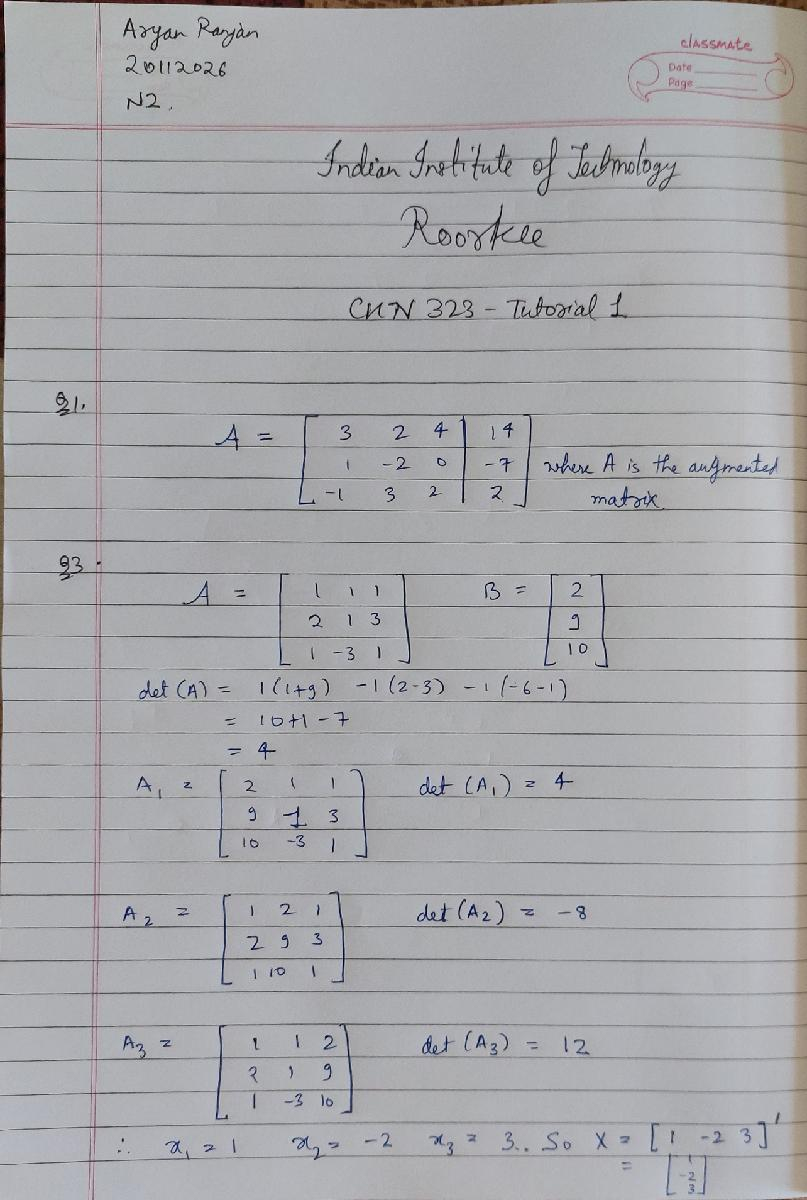

Q4. Solve the above problem by taking the inverse of the coefficient matrix...

% Sol 4
disp("As det(A) = "+ det(A)+ " (!= 0)")

As det(A) = 4 (!= 0)



disp("So, Inverse of the coefficient matrix inv(A) is:")

So, Inverse of the coefficient matrix inv(A) is:


inv(A)

ans =     2.5000   -1.0000    0.5000
    0.2500         0   -0.2500
   -1.7500    1.0000   -0.2500



disp("So, solution matrix X is X = inv(A) * B:")

So, solution matrix X is X = inv(A) * B:


X = inv(A) * B

X =     1.0000
   -2.0000
    3.0000


Q5. Solve the above problem by MATLAB in-built functions? What is the algorithm behind the in-built function?

% Sol 5
disp("Solution of the problem AX = B is:")

Solution of the problem AX = B is:


X = A\B

X =     1.0000
   -2.0000
    3.0000



%{
One of the algorithm behind the above built in
function "mldivide" is gauss eleminiation where
the coefficient matrix (A) is converted to a
triangular matrix
%}

Q6. Write a code in MATLAB to convert the above coefficient matrix (A) in Q3 to a lower and upper triangular matrix without changing other elements. 

% Sol 6
triu(A)

ans =      1     1     1
     0     1     3
     0     0     1


tril(A)

ans =      1     0     0
     2     1     0
     1    -3     1


Q7. Write a code in MATLAB to convert the above coefficient matrix (A) in Q3 to a column vector comprising the same 9 elements in order.

% Sol 7
C = [];

for i = 1:3
    C = [C; A(i,:)'];
end

disp("The value of column matrix C is:")

The value of column matrix C is:


C

C =      1
     1
     1
     2
     1
     3
     1
    -3
     1


timeTaken = toc;
disp("Total time elapsed = " + timeTaken);

Total time elapsed = 0.20806
